## 绘制直方图

## `直方图————histogram`

`命令: histogram`

`有两种用法: histogram(X) & [count,center] = histogram(X) -> bar(center,count)`

`功能:count = histogram(x)把向量X中的元素放入`**等距（有间隔）**`的10个条形中，且返回每一个`

`条形中的元素个数。`

`[count,center] = histogram(X)返回向量X中包含频率计数的count与条形的位置向量`

`center，可以用命令bar(center,count)画出条形直方图。`

### 1.向量直方图

法1：做1000个服从N（10，25）数据的直方图（有间隔）

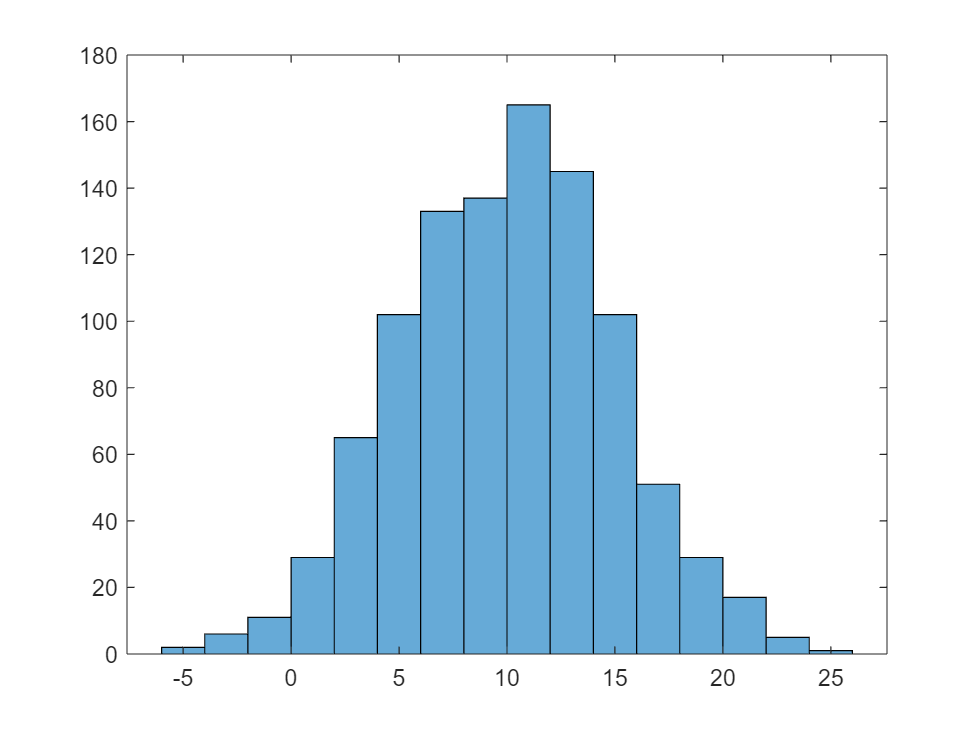

x = normrnd(10,5,1000,1);
histogram(x)

法2：间隔

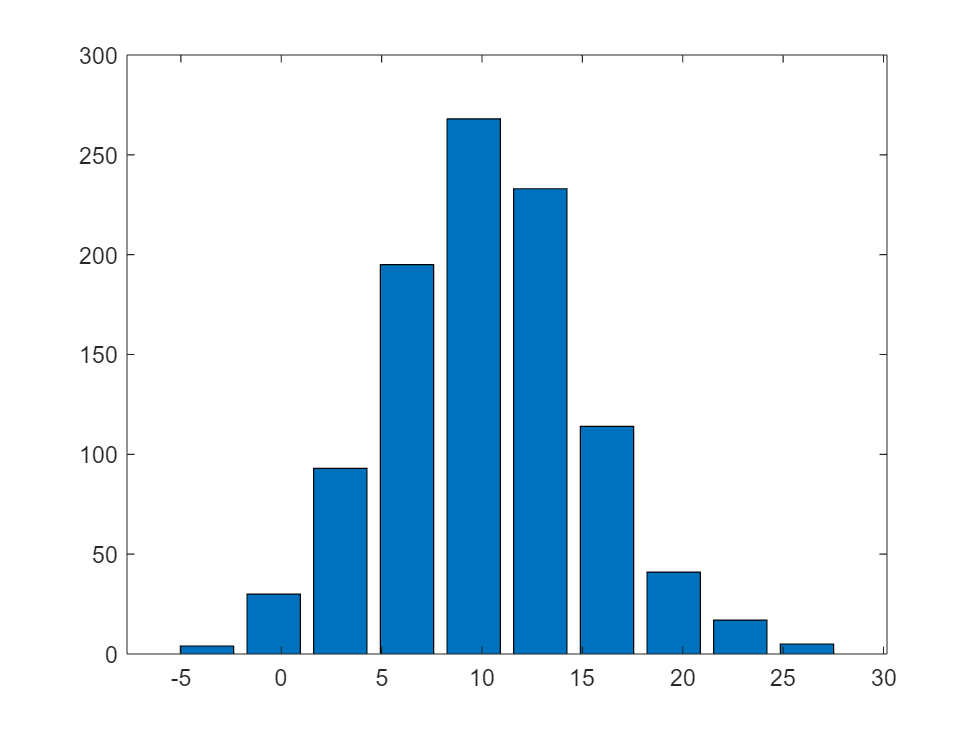

X=normrnd(10,5,1000,1);
[count,center]=histogram(X);
bar(center,count)

### 2.**指定直方图的 bin 数量**

对分类为 25 个等间距 bin 的 1,000 个随机数绘制直方图。

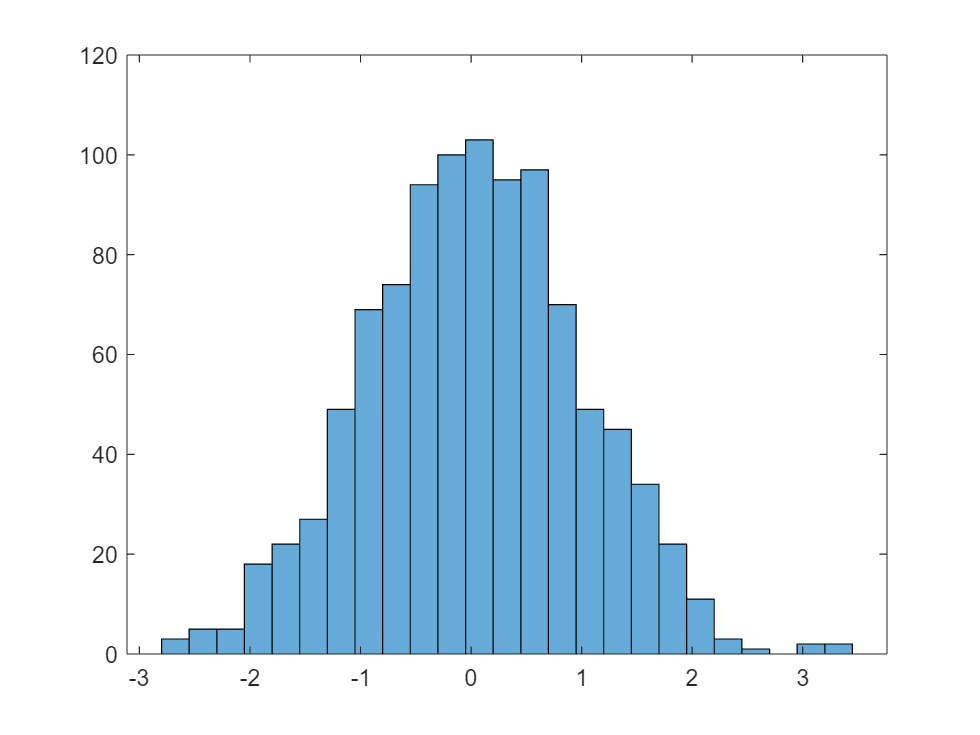

h =   Histogram - 属性:

             Data: [1000×1 double]
           Values: [3 5 5 18 22 27 49 69 74 94 100 103 95 97 70 49 45 34 22 11 3 1 0 2 2]
          NumBins: 25
         BinEdges: [-2.8000 -2.5500 -2.3000 -2.0500 -1.8000 -1.5500 -1.3000 -1.0500 -0.8000 -0.5500 -0.3000 -0.0500 0.2000 0.4500 0.7000 0.9500 1.2000 1.4500 1.7000 1.9500 2.2000 2.4500 2.7000 2.9500 3.2000 3.4500]
         BinWidth: 0.2500
        BinLimits: [-2.8000 3.4500]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  显示 所有属性


x = randn(1000,1);
nbins = 25;            % nbins 用于表示组数
h = histogram(x,nbins)

求 bin 计数。

counts = h.Values

counts =      3     5     5    18    22    27    49    69    74    94   100   103    95    97    70    49    45    34    22    11     3     1     0     2     2


### 3.**更改直方图的 bin 数量**

生成 1,000 个随机数并创建直方图。

X = randn(1000,1);
h = histogram(X)

h =   Histogram - 属性:

             Data: [1000×1 double]
           Values: [1 1 7 6 21 41 39 76 89 109 117 108 104 92 67 44 30 26 10 8 2 2]
          NumBins: 22
         BinEdges: [-3.3000 -3.0000 -2.7000 -2.4000 -2.1000 -1.8000 -1.5000 -1.2000 -0.9000 -0.6000 -0.3000 0 0.3000 0.6000 0.9000 1.2000 1.5000 1.8000 2.1000 2.4000 2.7000 3 3.3000]
         BinWidth: 0.3000
        BinLimits: [-3.3000 3.3000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  显示 所有属性


使用 `morebins` 函数**粗略调整 bin 数量**。

Nbins = morebins(h);
Nbins = morebins(h)

Nbins = 28

通过显式设置 bin 数**精细调整 bin**。

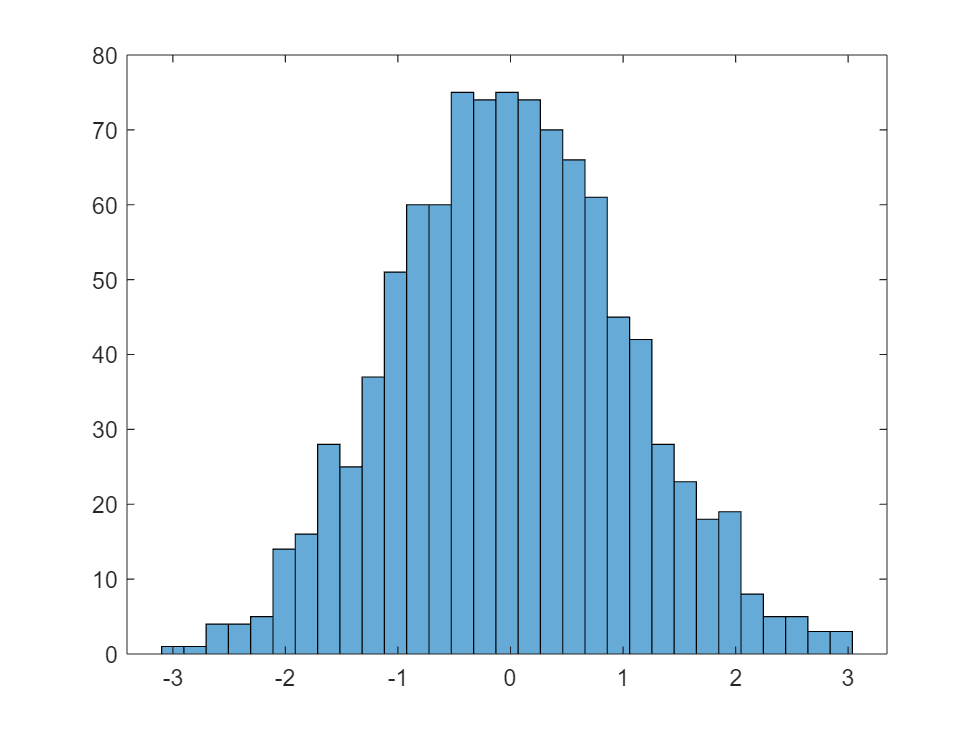

h.NumBins = 31;

### 4.**指定直方图的 bin 边界（没啥用）**

生成 1,000 个随机数并创建直方图。将 bin 边界指定为向量，使宽 bin 在直方图的两边，**以捕获不满足 **`∣``x``∣<2`** 的离群值**。第一个向量元素是第一个 bin 的左边界，而最后一个向量元素是最后一个 bin 的右边界。

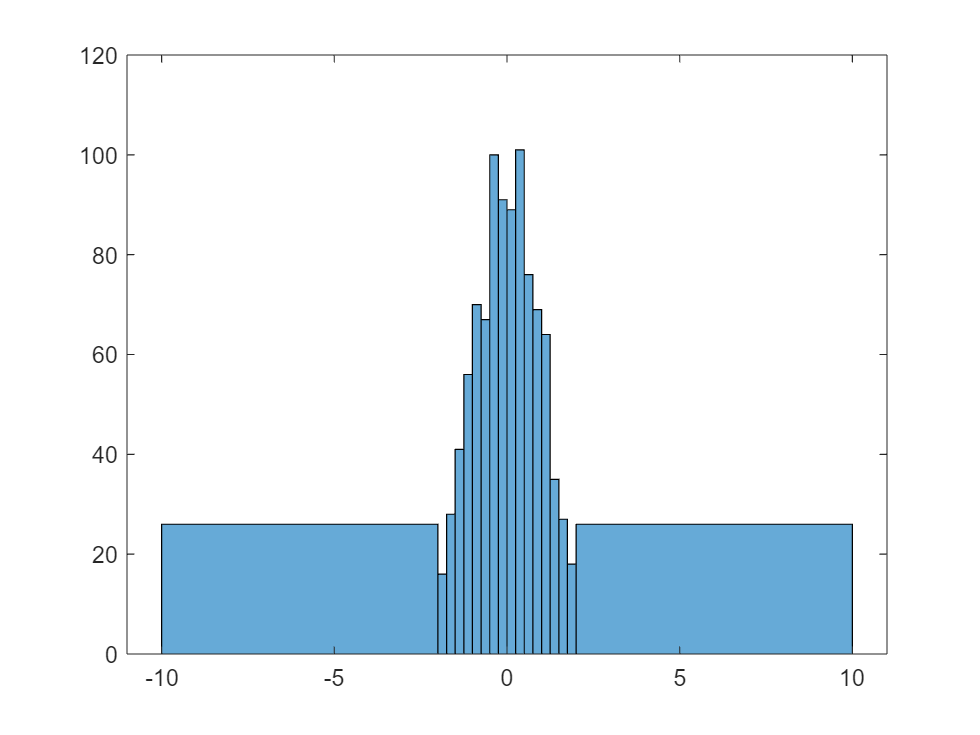

x = randn(1000,1);
edges = [-10 -2:0.25:2 10];
h = histogram(x,edges);

doc categorical